# Lab session IV:

## Intro:

On this Laboratory session we are going to work with the different attitude representations seen in class. 

- Exercise 1: 1 point. To be delivered before the end of the session.

- Exercise 2: 3 points

- Exercise 3: 3 points

- Exercise 4: 3 points

**Lab rules:**

- Always respect the delivery dates

- Use the templates when provided and DO NOT MODIFY THE FILE NAMES OR THE FUNCTION NAMES

- Verify that your code works before submit

- Always upload the files in a .zip with the name structure:  * Surname_Name.zip*

- Cheating is not allowed and will be firmly punished with a final mark of 0

This assignment is due to 

# Exercise 1:

The point p has coordinates

p_A = [3, 4]';

on a frame {A}, and coordinates

p_B = [-2.5, 0.5]';

on a frame {B}.

It is known that the angle between $x$-axis of frame {A} and the$y$ axes of the frame {B} is 30 deg counterclockwise.

aRb = [cosd(60) -sind(60); sind(60) cosd(60)];
bRa = [cosd(-60) -sind(-60); sind(-60) cosd(-60)];

##  1.1 Which are the coordinates of the origin of A seen from B?

 bDba = p_B-bRa*p_A

bDba =    -7.4641
    1.0981


##  1.2 Which are the coordinates of the origin of B seen from A?

aDab = p_A - aRb*p_B

aDab =     4.6830
    5.9151


##  1.3 Which are the coordinates of a point q expressed in A if 

q_B = [3,1]';
q_A = aRb*q_B+aDab 

q_A =     5.3170
    9.0131



%COMPROBACIÓN

norm(aDab)

ans = 7.5444

norm(bDba)

ans = 7.5444

# Exercise 2:

 Let {A}, {B} and {C}, be 3 different reference frames. From them we know that:

- The origin of B with respect A is

AoB = [3,1,-2]';

- The origin of C with respect B is

BoC = [-3, 1,-2]';

- The three frames has different orientations in space. In fact:  

- The set of Euler angles stored in $\eta$ as $\eta = (\psi,\theta,\phi)$

eta = [25;145;30]; % Expressed in degrees

                 represent 3 consecutive rotations about z, y, and x respectively that allows to transform vectors from {A} to {B}  (which imply $^B v = R(\psi, \theta, \phi)\, ^Av$)

- The quaternion

q = 1/7*[-sqrt(3)*3.5;3;-1;-1.5];

                 allows to express in {B} a vector defined in {C}, if {C} and {B} had the same origin

Let in addition v1 and v2 to be points which coordinates are known in  {C}.

v1_C = [0;2;0];
v2_C = [0;2;5];

With the information provided above determine:

##  2.1.1 The affine** expression** that allows to relate a vector originally given in {C} to {B}. Note that no calculations have to be provided here, only the expression which is not a matrix.

-

## 2.1.2 Implement a function called rotVbyq that provided a vector and a quaternion rotates the vector using quaternion multiplications. Test it and commet why do you think it is well implemented.

##  2.2 The affine matrix that allows to express a vector originally given in {C} to {A}.

## 2.3 The vectors v1_C and v2_C form a segment. Make a 3d plot (plot3() in matlab), representing how the segment is seen on {A} in red, on {B} in blue and on {C} in green.

# Exercise 3:

The points described by the columns of the matrix A 

A = load('AEx3.mat');
A = A.A;

are points contained into a circle, and they are defined in a world frame W.

A camera is situated at point

wc = [1; 6; 1];

 defined in the world frame. Moreover the orientation of this camera frame is achieved by rotating the world frame 90 degs about its y axis followed by -20 degrees about the resulting z axis.

If the camera has a focal length of 1/34 m:

##  3.1 Make a plot with the view of the points of the circle projected into the camera plane.

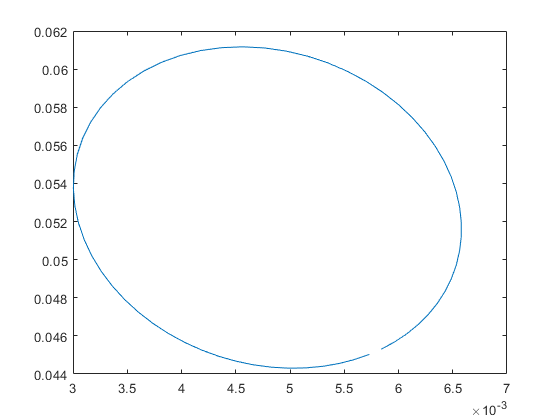

%Focal distance needed later
f_distance = 1/34;

%Axis were our matrix will rotate
u_Yaxis = [0 1 0]';
u_Zaxis = [0 0 1]';

%Rotating AEx3.mat[A]
First_Rotation = axis2RotMat(-90,u_Yaxis) * A;
Final_Rotation = axis2RotMat(-20,u_Zaxis) * First_Rotation;


Points_w2c = Final_Rotation + wc;
Circle_Projected = cameraproj(1, f_distance, Points_w2c);
plot(Circle_Projected(1,:), Circle_Projected(2,:))

##  3.2 Make also a 3D plot where all the scene is drawn in the world coordinates. The scene must contain the 2 reference frames (2 orthogonal sets of vectors) and the circle points. 

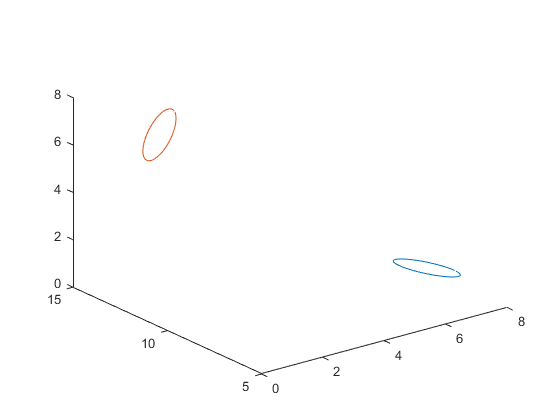

plot3(A(1,:), A(2,:), A(3,:));
hold on
plot3(Points_w2c(1,:), Points_w2c(2,:), Points_w2c(3,:))
hold off

You can use the provided function cameraproj.

# Exercise 4:

The columns of the next matrix, represents the coordinates od 4 points defined in a world frame.

A = load('AEx4.mat');
A = A.A

A =     0.9115    3.7207    1.9659    2.6663
    1.9397    2.8794    1.0000    3.8191
    3.3304    4.4372    3.2588    4.5087


From this 4 points, two segments are defined. The segment one, goes from the point defined by the first column to the point defined by the second column. The second segment is defined by the other two points.

 A camera frame is seeing the scene. The origin of the world frame seen from the camera frame is given by the vector

wc = [4.665;3.735;-0.5395];

And the orientation of the camera frame is obtained after rotating the world frame -150 degs about the direction

u = [0.01;-.2;1];

With the data provided determine:

## 4.1 The minimum angle that both segments forms (hint, they intersect)

f = 1/40;
A1 = A(:,1);
A2 = A(:,2);
B1 = A(:,3);
B2 = A(:,4);

SA = A2 - A1;
SB = B2 - B1;

angleW = acosd((abs(dot(SA, SB))) / (norm(SA) * norm(SB)))

angleW = 53.1301

## 4.2 The angle that both segments forms in the image plane

A1I = axis2RotMat(150, u) * A1 + wc;
A2I = axis2RotMat(150, u) * A2 + wc;
B1I = axis2RotMat(150, u) * B1 + wc;
B2I = axis2RotMat(150, u) * B2 + wc;

A1I = cameraproj(1, f, A1I);
A2I = cameraproj(1, f, A2I);
B1I = cameraproj(1, f, B1I);
B2I = cameraproj(1, f, B2I);

SA = A2I - A1I;
SB = B2I - B1I;

angleI = acosd((abs(dot(SAI, SBI))) / (norm(SAI) * norm(SBI)))

angleI = 38.6714

## 4.3 Deliver a 3D representation of the scene with all the coordinates refered to the world frame

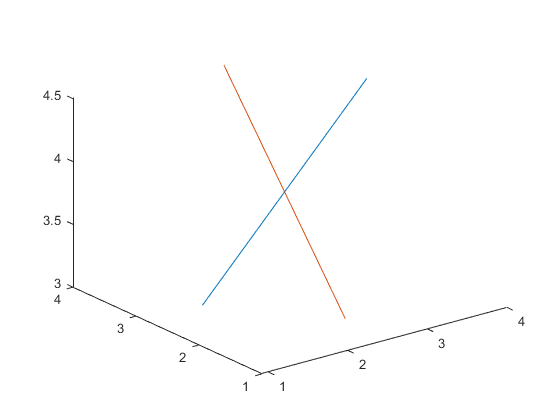

  
plot3([A1(1), A2(1)],[A1(2), A2(2)],[A1(3), A2(3)]);
hold on
plot3([B1(1), B2(1)],[B1(2), B2(2)],[B1(3), B2(3)]);
hold off

## 4.4 Deliver the same 3D scene representations but with all the coordinates refered to the camera frame

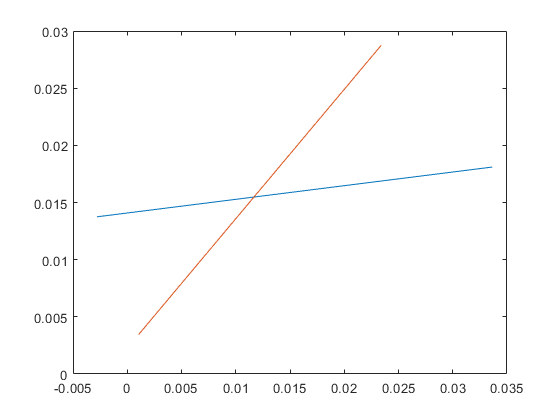

A1 = A(:,1);
A2 = A(:,2);
B1 = A(:,3);
B2 = A(:,4);

%Esto es el plano imagen, pero aqui te pide el frame de la camara

plot([A1I(1), A2I(1)],[A1I(2), A2I(2)]);
hold on
plot([B1I(1), B2I(1)],[B1I(2), B2I(2)]);
hold off

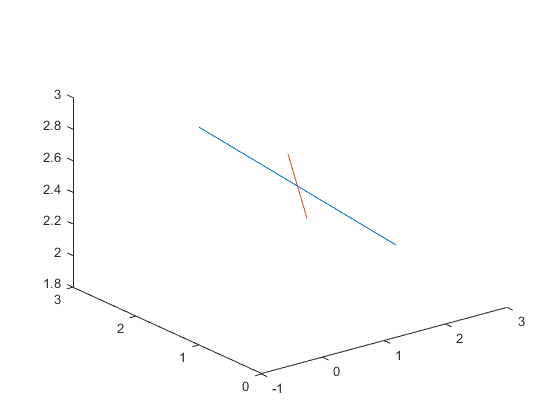

A1C = axis2RotMat(150, u) * A1 + wc;
A2C = axis2RotMat(150, u) * A2 + wc;
B1C = axis2RotMat(150, u) * B1 + wc;
B2C = axis2RotMat(150, u) * B2 + wc;

plot3([A1C(1), A2C(1)],[A1C(2), A2C(2)],[A1C(3), A2C(3)]);
hold on
plot3([B1C(1), B2C(1)],[B1C(2), B2C(2)],[B1C(3), B2C(3)]);
hold off